# Experiment 2_3

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Mohammad Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 3: Voice scrambling

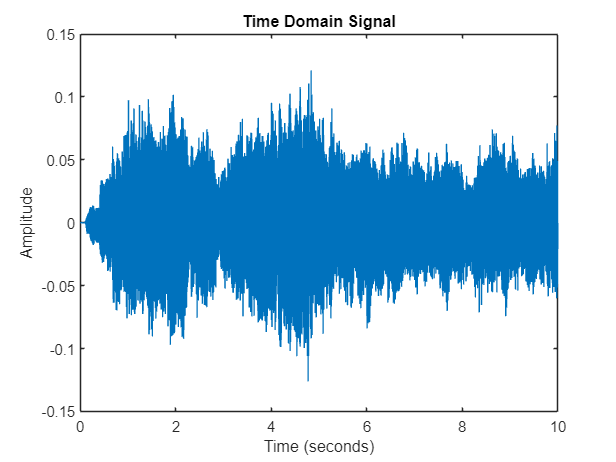

%2-3-1
% Load the audio file
[x, fs] = audioread('Audio01.wav');

% Time vector
t = (0:length(x)-1)/fs;

% Plot in time domain
figure;
plot(t, x);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Time Domain Signal');

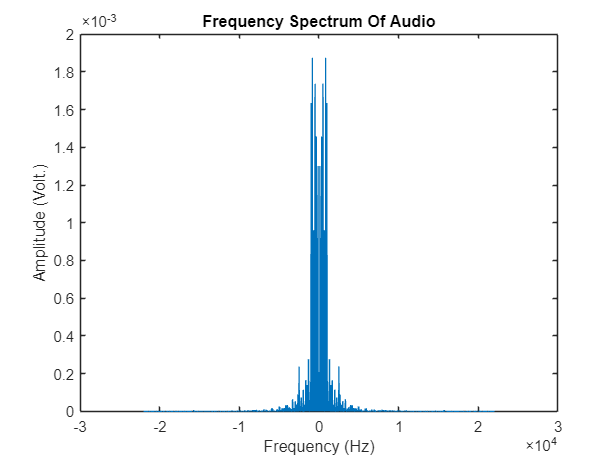


n = length(x);
X = fft(x);
X_shifted = fftshift(abs(X)/n);  % Normalized and shifted FFT
f = (-n/2:n/2-1)*(fs/n);         % Frequency vector centered around 0

figure;
plot(f, X_shifted);
xlabel('Frequency (Hz)');
ylabel('Amplitude (Volt.)');
title('Frequency Spectrum Of Audio');



% Play the sound
sound(x, fs);

% Pause for the duration of the audio to prevent overlap
pause(length(x)/fs);


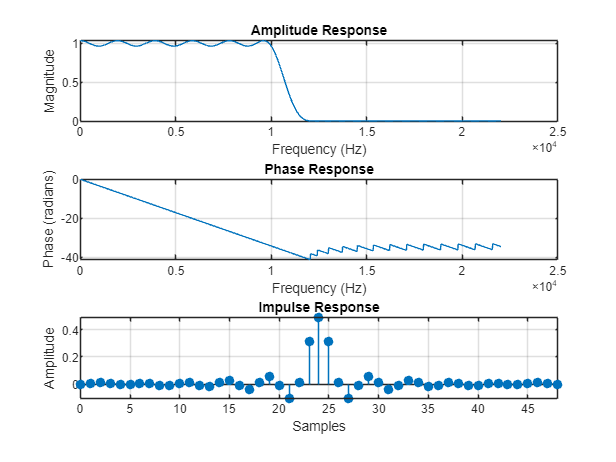

% 2-3-2
% Load filter coefficients from file
load('filter.mat');  % Assumes 'Num' is stored in the file

% Define sampling frequency
fs = 44100;

% Compute frequency response
[H, f] = freqz(Num, 1, 1024, fs);  % 1024 points, freq in Hz

% Plot Amplitude and Phase Response
figure;
subplot(3,1,1);
plot(f, abs(H));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude Response');
grid on;

subplot(3,1,2);
plot(f, unwrap(angle(H)));
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Response');
grid on;

% Plot Time-Domain (Impulse) Response
subplot(3,1,3);
impz(Num, 1);  % or use stem(0:length(Num)-1, Num)
xlabel('Samples');
ylabel('Amplitude');
title('Impulse Response');
grid on;

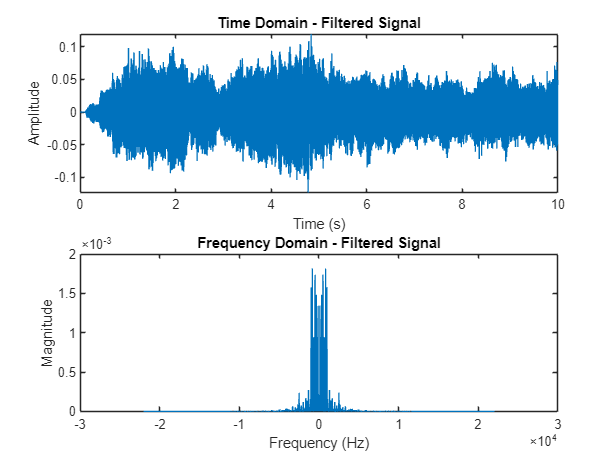

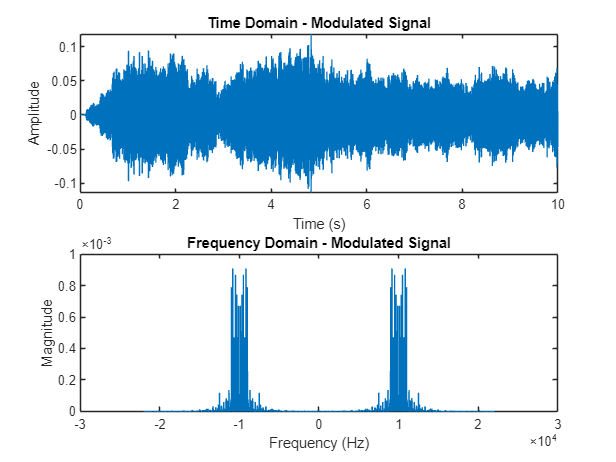

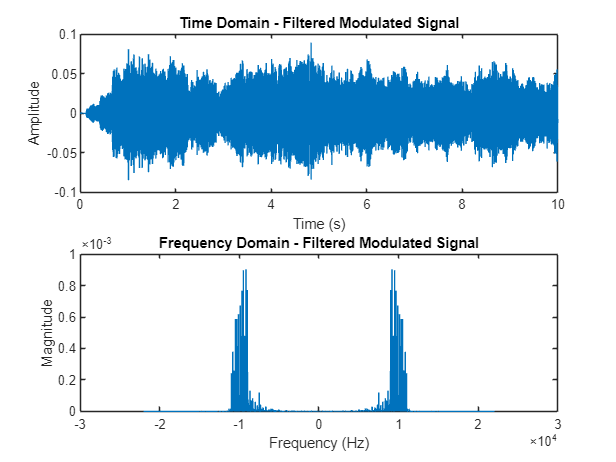

% 2-3-3
%% 2-3-3: Filter → Modulate → Filter Again

% --- Step 1: Apply the filter ---
x_filtered = filter(Num, 1, x);

% --- Step 2: Multiply by carrier (AM modulation) ---
fc = 10000;  % Carrier frequency (10 kHz)
t = (0:length(x_filtered)-1)/fs;
carrier = cos(2*pi*fc*t)';
x_modulated = x_filtered .* carrier;

% --- Step 3: Pass through filter again (demodulation)
x_demodulated = filter(Num, 1, x_modulated);

% --- Plot time and frequency domain for all three stages ---

signals = {x_filtered, x_modulated, x_demodulated};
titles = {'Filtered Signal', 'Modulated Signal', 'Filtered Modulated Signal'};
n = length(x);
f = (-n/2:n/2-1)*(fs/n);

for i = 1:3
    x_stage = signals{i};
    % Time domain
    figure;
    subplot(2,1,1);
    plot(t, x_stage);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Time Domain - ' titles{i}]);

    % Frequency domain
    Xf = fftshift(abs(fft(x_stage))/n);
    subplot(2,1,2);
    plot(f, Xf);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Domain - ' titles{i}]);
end


% --- Listen to final signal ---
sound(x_demodulated, fs);


% 2-3-4
%% 2-3-4: Descramble the signal to recover the original audio

% --- Step 1: Scrambled signal (x_demodulated from before)
x_scrambled = x_demodulated;

% --- Step 2: Multiply by carrier again (second modulation) ---
x_scrambled_modulated = x_scrambled .* carrier;

% --- Step 3: Pass through filter again (demodulation) ---
x_descrambled = filter(Num, 1, x_scrambled_modulated);

% --- Listen to recovered audio ---
sound(x_descrambled, fs);
pause(length(x_descrambled)/fs);

% --- Compute Error Metrics ---
mae = mean(abs(x - x_descrambled(1:length(x))));
mse = mean((x - x_descrambled(1:length(x))).^2);

fprintf('Mean Absolute Error (MAE): %f\n', mae);

Mean Absolute Error (MAE): 0.019023


fprintf('Mean Squared Error (MSE): %f\n', mse);

Mean Squared Error (MSE): 0.000591


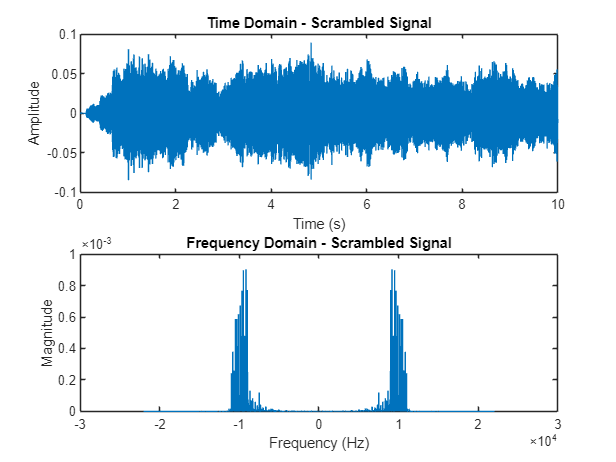

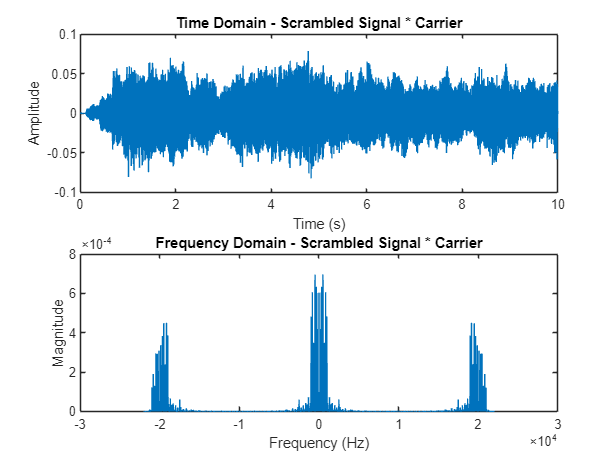

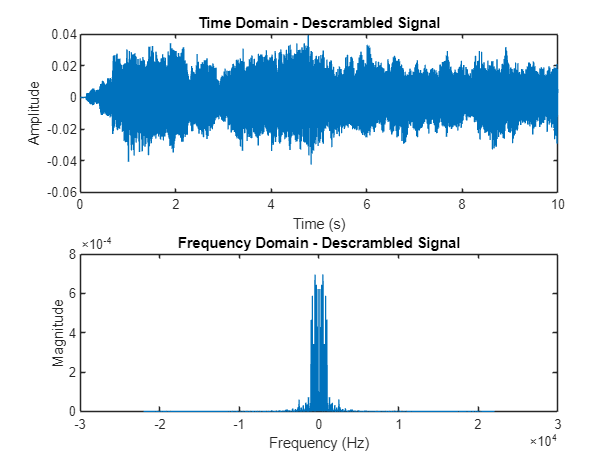


%% Plot Scrambled, Scrambled*Carrier, and Descrambled in Time and Frequency Domains

signals = {x_scrambled, x_scrambled_modulated, x_descrambled};
titles = {'Scrambled Signal', 'Scrambled Signal * Carrier', 'Descrambled Signal'};
n = length(x);
f = (-n/2:n/2-1)*(fs/n);
t = (0:length(x)-1)/fs;

for i = 1:3
    x_stage = signals{i};
    x_stage = x_stage(1:length(x));  % Match length to original

    % Time domain
    figure;
    subplot(2,1,1);
    plot(t, x_stage);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Time Domain - ' titles{i}]);

    % Frequency domain
    Xf = fftshift(abs(fft(x_stage))/n);
    subplot(2,1,2);
    plot(f, Xf);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Domain - ' titles{i}]);
end

%% 2-3-4: Descramble the signal to recover the original audio (with noise)

% --- Step 1: Scrambled signal (x_demodulated from before) ---
x_scrambled = x_demodulated;

% --- Step 2: Add Gaussian noise to scrambled signal ---
snr_dB = 1;  % Signal-to-noise ratio in dB
x_scrambled_noisy = awgn(x_scrambled, snr_dB, 'measured');

% --- Step 3: Multiply noisy scrambled signal by carrier again ---
x_scrambled_modulated_noisy = x_scrambled_noisy .* carrier;

% --- Step 4: Pass through filter again (demodulation) ---
x_descrambled_noisy = filter(Num, 1, x_scrambled_modulated_noisy);

% --- Listen to recovered noisy audio ---
sound(x_descrambled_noisy, fs);
pause(length(x_descrambled_noisy)/fs);

% --- Compute Error Metrics ---
x_trimmed = x(1:length(x_descrambled_noisy));  % Match lengths
mae_noisy = mean(abs(x_trimmed - x_descrambled_noisy(1:length(x_trimmed))));
mse_noisy = mean((x_trimmed - x_descrambled_noisy(1:length(x_trimmed))).^2);

fprintf('Noisy Signal - Mean Absolute Error (MAE): %f\n', mae_noisy);

Noisy Signal - Mean Absolute Error (MAE): 0.019757


fprintf('Noisy Signal - Mean Squared Error (MSE): %f\n', mse_noisy);

Noisy Signal - Mean Squared Error (MSE): 0.000631


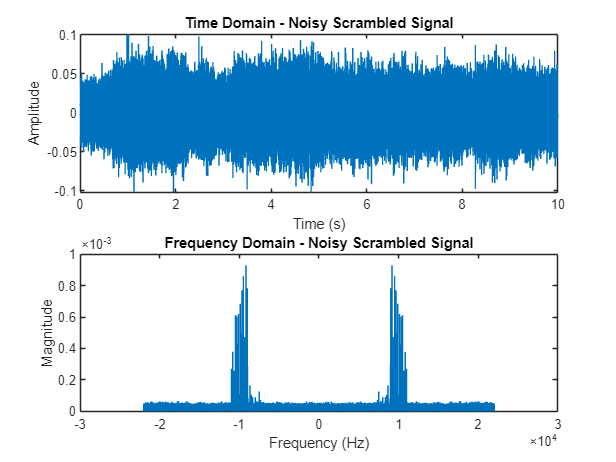

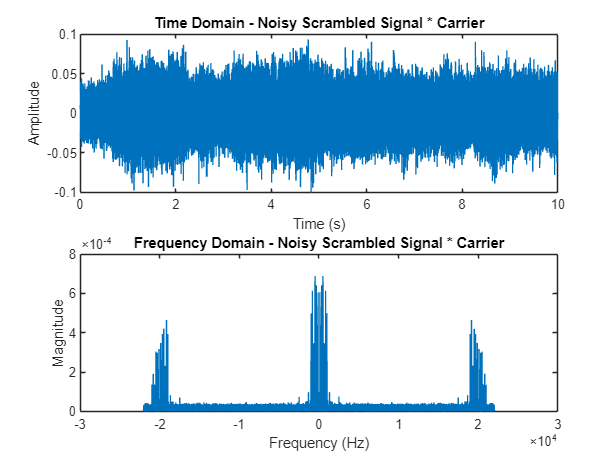

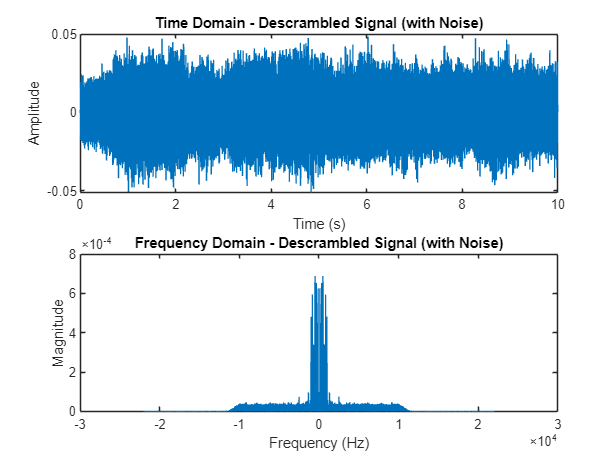


% --- Plot Scrambled, Noisy Scrambled*Carrier, and Descrambled in Time and Frequency Domains ---
signals = {x_scrambled_noisy, x_scrambled_modulated_noisy, x_descrambled_noisy};
titles = {'Noisy Scrambled Signal', 'Noisy Scrambled Signal * Carrier', 'Descrambled Signal (with Noise)'};
n = length(x);
f = (-n/2:n/2-1)*(fs/n);
t = (0:length(x)-1)/fs;

for i = 1:3
    x_stage = signals{i};
    x_stage = x_stage(1:length(x));  % Match length to original

    % Time domain
    figure;
    subplot(2,1,1);
    plot(t, x_stage);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Time Domain - ' titles{i}]);

    % Frequency domain
    Xf = fftshift(abs(fft(x_stage))/n);
    subplot(2,1,2);
    plot(f, Xf);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Domain - ' titles{i}]);
end

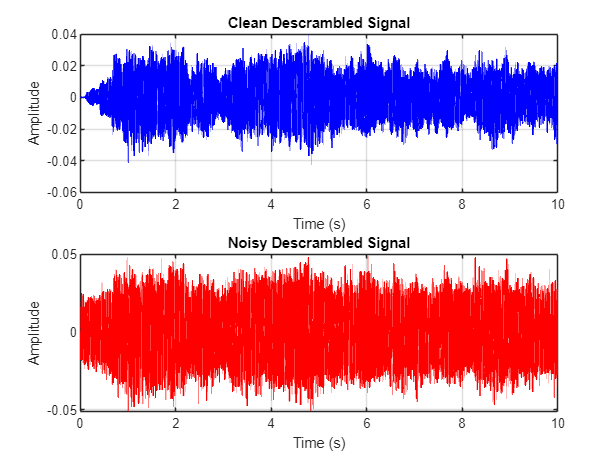

% Ensure both signals are same length as original
x_clean_full = x_descrambled(1:length(x));
x_noisy_full = x_descrambled_noisy(1:length(x));

% Time vector (full duration)
t_full = (0:length(x_clean_full)-1)/fs;

% Plot clean and noisy descrambled signals
figure;

% Subplot 1: Clean descrambled signal
subplot(2,1,1);
plot(t_full, x_clean_full, 'b', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean Descrambled Signal');
grid on;

% Subplot 2: Noisy descrambled signal
subplot(2,1,2);
plot(t_full, x_noisy_full, 'r', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Descrambled Signal');
grid on;

#### Part 4: Discrete Fourier Transform, Short-Time Fourier Transform and Wavelet Transform

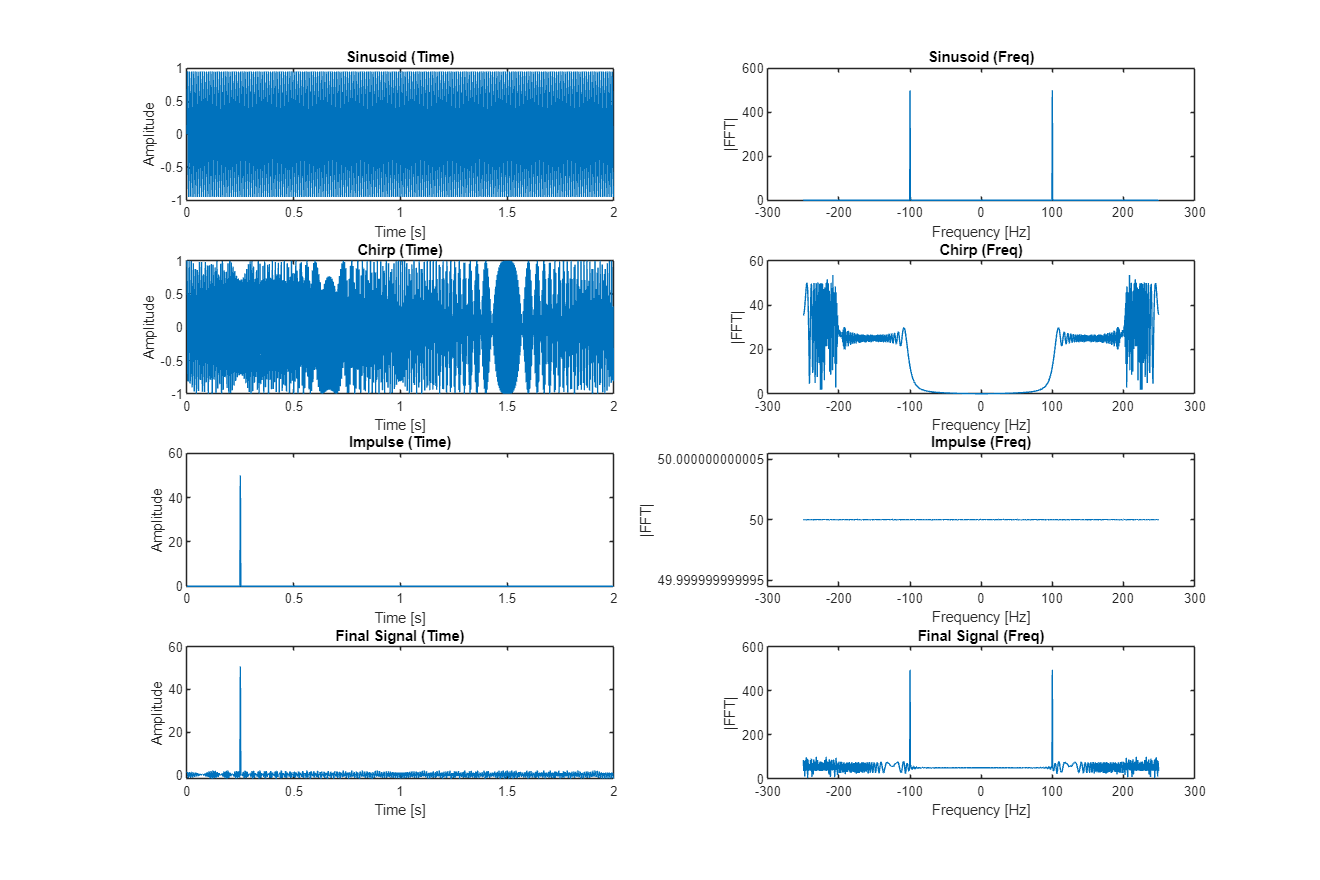

% Parameters
fs = 500;                  % Sampling frequency
T = 1/fs;                  % Sampling period
t = 0:T:2-T;               % Time vector (length = 2 seconds)
N = length(t);             % Number of samples
f = (-N/2:N/2-1)*(fs/N);   % Frequency vector for fftshift

% 1. Sinusoidal signal
sinusoid = sin(2*pi*100*t);

% 2. Chirp signal (linear from 400 Hz to 200 Hz)
chirp_signal = chirp(t, 400, 2, 200);

% 3. Impulse signal at 0.25s with amplitude 50
impulse = zeros(size(t));
impulse_index = round(0.25 * fs) + 1;  % +1 for MATLAB indexing
impulse(impulse_index) = 50;

% 4. Final signal
final_signal = sinusoid + chirp_signal + impulse;

% FFT with fftshift
get_fftshift_mag = @(x) abs(fftshift(fft(x)));

Y_sin = get_fftshift_mag(sinusoid);
Y_chirp = get_fftshift_mag(chirp_signal);
Y_impulse = get_fftshift_mag(impulse);
Y_total = get_fftshift_mag(final_signal);

% Plotting
figure;
set(gcf, 'Position', [100, 100, 1200, 800]);  % Bigger window

% Time Domain Plots
subplot(4,2,1);
plot(t, sinusoid); title('Sinusoid (Time)');
xlabel('Time [s]'); ylabel('Amplitude');

subplot(4,2,3);
plot(t, chirp_signal); title('Chirp (Time)');
xlabel('Time [s]'); ylabel('Amplitude');

subplot(4,2,5);
plot(t, impulse); title('Impulse (Time)');
xlabel('Time [s]'); ylabel('Amplitude');

subplot(4,2,7);
plot(t, final_signal); title('Final Signal (Time)');
xlabel('Time [s]'); ylabel('Amplitude');

% Frequency Domain Plots (centered)
subplot(4,2,2);
plot(f, Y_sin); title('Sinusoid (Freq)');
xlabel('Frequency [Hz]'); ylabel('|FFT|');

subplot(4,2,4);
plot(f, Y_chirp); title('Chirp (Freq)');
xlabel('Frequency [Hz]'); ylabel('|FFT|');

subplot(4,2,6);
plot(f, Y_impulse); title('Impulse (Freq)');
xlabel('Frequency [Hz]'); ylabel('|FFT|');

subplot(4,2,8);
plot(f, Y_total); title('Final Signal (Freq)');
xlabel('Frequency [Hz]'); ylabel('|FFT|');

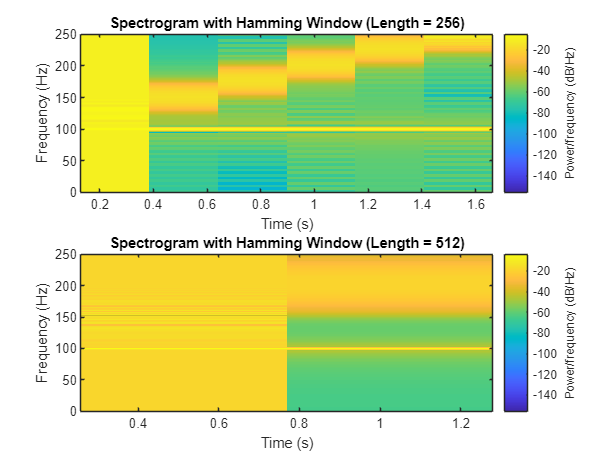

% Signal setup from previous steps (use final_signal as defined earlier)

% Common parameters
fs = 500;

% Window lengths to compare
win1 = hamming(256);
win2 = hamming(512);

% Overlap (commonly 50% of window length)
overlap1 = 128;
overlap2 = 256;

% FFT length (can be equal to window length or larger)
nfft1 = 512;
nfft2 = 512;

% STFT using window length = 256
figure;
subplot(2,1,1);
spectrogram(final_signal, win1, overlap1, nfft1, fs, 'yaxis');
title('Spectrogram with Hamming Window (Length = 256)');

% STFT using window length = 512
subplot(2,1,2);
spectrogram(final_signal, win2, overlap2, nfft2, fs, 'yaxis');
title('Spectrogram with Hamming Window (Length = 512)');

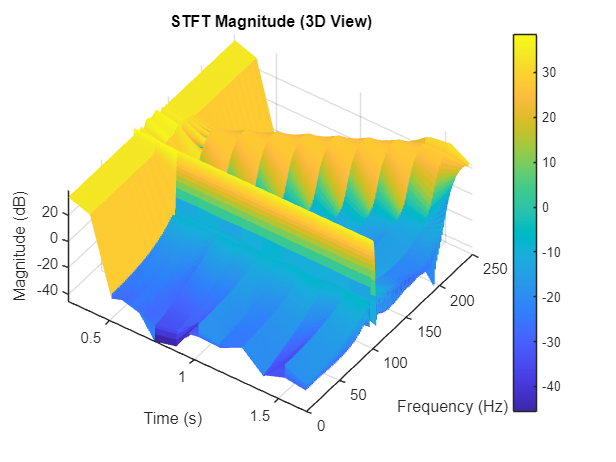

% Assumes 'final_signal' and 'fs' already defined

% Parameters
win_len = 256;
window = hamming(win_len, 'periodic');
overlap = round(0.75 * win_len);  % 75% overlap
nfft = 2048;

% STFT
[s, f_stft, t_stft] = stft(final_signal, fs, ...
    'Window', window, ...
    'OverlapLength', overlap, ...
    'FFTLength', nfft);

% Convert to decibels
S_dB = 20*log10(abs(s) + eps);  % eps to avoid log(0)

% Filter positive frequencies only
pos_idx = f_stft >= 0;
f_pos = f_stft(pos_idx);
S_pos_dB = S_dB(pos_idx, :);

% 3D Plot
figure;
surf(t_stft, f_pos, S_pos_dB, 'EdgeColor', 'none');
axis tight;
view(35, 60);  % 3D perspective
xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Magnitude (dB)');
title('STFT Magnitude (3D View)');
colorbar;

**Difference Between DFT and STFT**

The **Discrete Fourier Transform (DFT)** analyzes the entire signal as a whole and shows which frequencies are present, but it does not tell you **when** those frequencies occur. This works well if the signal is stationary (i.e., its frequency content doesn't change over time).

In contrast, the **Short-Time Fourier Transform (STFT)** breaks the signal into short overlapping time windows and computes the Fourier Transform for each window. This produces a **time-varying spectrum**, allowing us to see **how the frequency content changes over time**. The STFT is especially useful for non-stationary signals like chirps or signals with impulses.

**Effect of Window Length on Time and Frequency Resolution**

The length of the window used in the STFT affects the balance between **time resolution** and **frequency resolution**:

- A **shorter window** (e.g., length 256):

- Gives **better time resolution** (you can see quick changes more clearly)

- But has **poorer frequency resolution** (frequency bands are wider and less precise)

- A **longer window** (e.g., length 512):

- Gives **better frequency resolution** (you can distinguish close frequencies better)

- But has **poorer time resolution** (quick changes are blurred)

This is a trade-off: you can't have high resolution in both time and frequency at the same time. This is known as the **time-frequency uncertainty principle**.

**Effect of Overlap**

The **overlap** between adjacent windows (commonly 50%) improves the smoothness of the spectrogram:

- More overlap → smoother transitions and better tracking of changes

- Less overlap → faster computation, but possibly choppier results